# **CAN - Working with the DB Parser**

This example demonstrates sending and receiving CAN messages via a loopback connection of two CAN ports with Simulink® signals mapped to CAN messages using the [DB Parser Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_read) and [DB Parser Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_write) blocks. Currently this example can be used with the IO602, IO603 and the IO691. 

The example performs data transfer with a loopback, by sending CAN messages from channel 1 to channel 2. The following blocks are used: [DB Parser Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_read), [DB Parser Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_write).

This example demonstrates the following modes and features:

- Sending and receiving CAN messages using the DB Parser blocks

- database (.dbc) file parsing and signal mapping

- Cyclic transmission of CAN messages

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with an IO602, IO603 or an IO691 CAN I/O module installed

- 1x CAN Loopback test cable with terminator resistor (120 Ω)

### Connection Diagram

To run this example, the CAN channel 1 and channel 2 must be connected with a terminated CAN cable. As this example can be executed either with an IO602, IO603 or an IO691, refer to the pin mapping for your CAN I/O module to connect channel 1 and channel 2:

[IO602-2 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io602_2_pin_mapping)/[IO602-4 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io602_4_pin_mapping)/[IO603 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io603_pin_mapping)/[IO691 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io691_pin_mapping)

## Open and Configure the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_CAN_ParsingAndMapping';
open_system(modelName);

### Select CAN I/O Module

In the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block, select the specific CAN I/O module that you are using. A unique **Module ID** is set in every [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block to link the [DB Parser Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_read) and [DB Parser Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_write) blocks in the rest of the model to this Setup block. If there is only one IO602, IO603 or IO691 in the target, the **Module ID** can always remain at 1.

 
% open the CAN setup block to select your CAN I/O module
speedgoat.model.highlight([modelName '/CAN and LIN Setup 1'],'Parameter','moduleType');

### Specify CAN channels

After selecting the correct CAN I/O module, channel 1 and channel 2 will be configured for the CAN operating mode. You can do this with the dropdown in the mask or with the following code section. Unused CAN channels can be disabled.

 
% configure CAN channel 1 and 2 to CAN FD
set_param([modelName '/CAN and LIN Setup 1'],'canChn1','CAN (HS)');
set_param([modelName '/CAN and LIN Setup 1'],'canChn2','CAN (HS)');

When a channel is enabled, the baud rate can be configured in the tab that is shown for each channel.

## Model Description

The model includes a simple vehicle dynamics model and an instrumentation dashboard. The CAN messages received are processed by various subsystems, and the resulting signals are transmitted again to the CAN bus.

You have already used the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block to configure the CAN I/O module with its channels. The remaining items to configure are the [DB Parser Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_read) and [DB Parser Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_write) blocks, to parse the database file and map Simulink signals to CAN signals.

### CAN DB Parser Read Configuration

 
% open the CAN DB Parser Read block to configure the .dbc file and enable all CAN messages to be
% received from the bus
speedgoat.model.highlight([modelName '/CAN DB Parser Read ']);

To send and receive CAN messages, a database file (.dbc) is required and must be configured in the [DB Parser Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_read) block. The application can be opened by double-clicking on the block. Clicking the **Database Manager** button will open another window to add the **canConnectivityForVehicle.dbc** file provided. From this .dbc file you have to generate a .slx library using either the **Generate** or **Update All Libraries **button. The CAN Database Manager can then be closed. By selecting the **Enable All** checkbox in the [DB Parser Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_read) application, all the enabled/selected CAN messages are received by this block.

The **CAN I/O Module** and the **Channel Number** are configured by default to the module with ID 1 and channel 1. The **Sample Time** should be defined according to the application, in the case of this model the value must be 0.01s.

The configuration can be applied by pressing **OK.** The application will close automatically.

### CAN DB Parser Write Configuration

 
% open the CAN DB Parser Write block to configure the .dbc-file and map Simulink signals to a CAN
% message to be transmitted
speedgoat.model.highlight([modelName '/CAN DB Parser Write ']);

As the .dbc file for this model has already been configured, it can simply be selected in the [DB Parser Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_write) block. The application can be opened by double-clicking on the block. First you have to select the **CAN I/O Module** (same as the one selected in the [DB Parser Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_read) block) and the **Channel Number, ** either channel 1 or 2 (the channel must be different from the one selected in the [DB Parser Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_read) block). Next, select the previously configured **canConnectivityForVehicle.dbc** in the **Database** dropdown. Again, select the **Enable All** checkbox to enable all the CAN Messages to be transmitted by this block.

Switching to the **Mapping** tab of the open application, all of the Simulink Bus elements connected to the input port of this block can be viewed by selecting the **Expand All** checkbox. These signals then have to be mapped to the respective CAN signal entries in the table on the right-hand side. To do so, select the Simulink signal in the tree view and the corresponding row in the table, then map them using the blue arrow button between the two displays. The **BrakeCommand **Simulink signal must therefore be mapped to the **BrakeCommand** CAN signal and so on. Not all of the Simulink signals or CAN signals must be mapped; this is the case for the **Control** signal. 

To enable cyclic transmission of CAN messages, the **Use Cycle Times from Database** checkbox has to be enabled and the **Sample Time** configured accordingly. The latter setting must satisfy the common divider requirement in relation to all **CycleTime** entries of this .dbc file (visible in the **Messages** tab). The largest common divider of the configured .dbc file is 0.01s. The **Sample Time** must therefore be set to this value.

The configuration can be applied by pressing **OK.** The application will close automatically.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
open_system(modelName); % go to top level
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download the real-time application to the target machine and set the stop time
tg.load(modelName);
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   
set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Wait until the real-time application reaches the stop time of 10 seconds

### Results

Check the scopes for the [DB Parser Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing_read) blocks to see if the loopback is working. The screenshots below show the expected outcome. 

You can change the speed parameters on the instrument dashboard. Any changes should be reflected immediately in the scopes and also on the dashboard.

 
% open Simulink scopes
speedgoat.model.highlight([modelName '/Scope_DB_Read'],'Open',true);
% open up instrumentation dashboard
speedgoat.model.highlight([modelName, '/Instrumentation'], 'Open', true);

**CAN DB Parser Read**

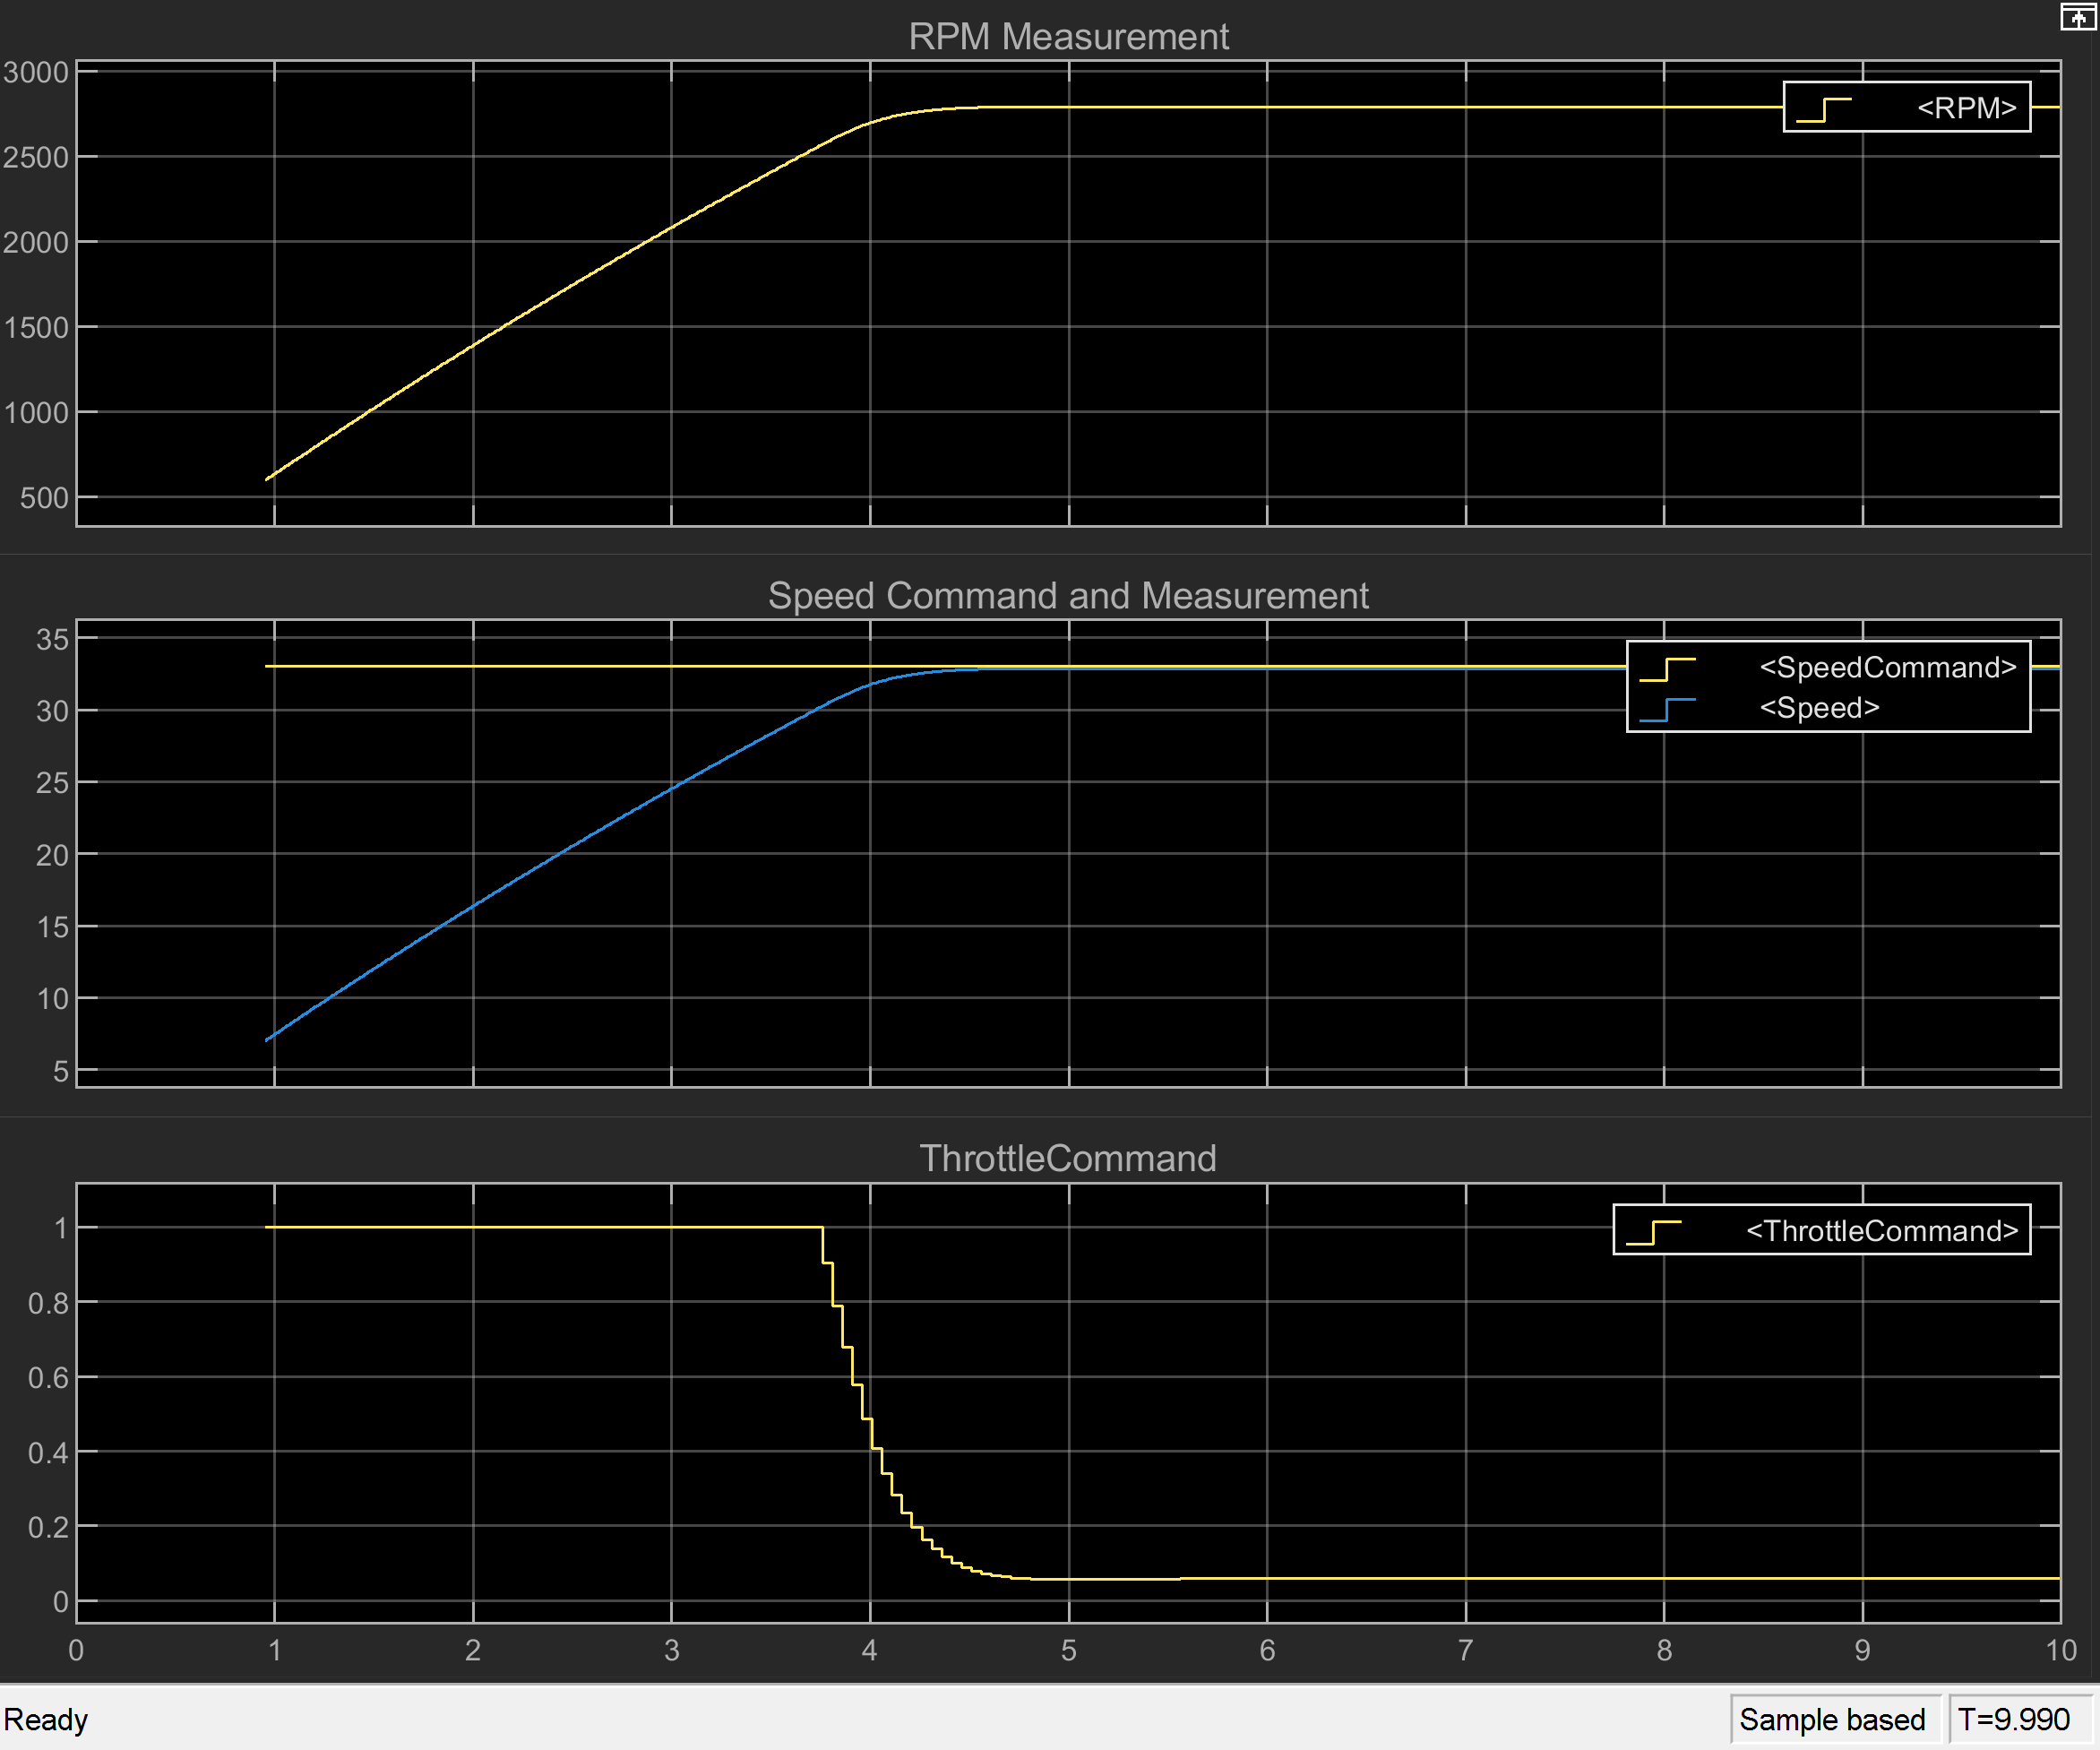

## Additional References

- [IO602/IO603/IO691 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa)

- [CAN Database Parser documentation page](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_parsing)

- [CAN Database Parser usage notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_can_ofa_parsing_usage_notes)